显式欧拉法步长0.025

clc
clear
clf ('reset')
Hfun=@(x,y)(-2/x*y+x.^(-2)*exp(x));
t = [1 2];
h = 0.025;
y0 = 0;
[X1,Y1] = ODE_ExplicitEuler( Hfun,t,h,y0 );
Y2=zeros(1,41);
Y3=zeros(1,41);
for i=1:41
Y2(i)=abs(Y1(i)-X1(i).^(-2)*(exp(X1(i))-exp(1)));
Y3(i)=X1(i).^(-2)*(exp(X1(i))-exp(1));
Y2=Y2.';
Y3=Y3.';
end
hold on
plot(X1,Y1);
plot(X1,Y3);
hold off
TAB=table(X1,Y1,Y3,Y2)

显式欧拉法步长0.1

clc
clear
clf ('reset')
Hfun=@(x,y)(-2/x*y+x.^(-2)*exp(x));
t = [1 2];
h = 0.1;
y0 = 0;
[X1,Y1] = ODE_ExplicitEuler( Hfun,t,h,y0 );
Y2=zeros(1,11);
Y3=zeros(1,11);
for i=1:11
Y2(i)=abs(Y1(i)-X1(i).^(-2)*(exp(X1(i))-exp(1)));
Y3(i)=X1(i).^(-2)*(exp(X1(i))-exp(1));
end
Y2=Y2.';
Y3=Y3.';
hold on
plot(X1,Y1);
plot(X1,Y3);
hold off
TAB=table(X1,Y1,Y3,Y2)

隐式欧拉法步长0.025

clc
clear
clf ('reset')
Hfun=@(x,y)(-2/x*y+x.^(-2)*exp(x));
t = [1 2];
h = 0.025;
y0 = 0;
[X1,Y1] = ODE_ImplicitEuler( Hfun,t,h,y0 );
Y2=zeros(1,41);
Y3=zeros(1,41);
for i=1:41
Y2(i)=abs(Y1(i)-X1(i).^(-2)*(exp(X1(i))-exp(1)));
Y3(i)=X1(i).^(-2)*(exp(X1(i))-exp(1));
end
Y2=Y2.';
Y3=Y3.';
hold on
plot(X1,Y1);
plot(X1,Y3);
hold off
TAB=table(X1,Y1,Y3,Y2)

隐式欧拉法步长0.1

clc
clear
clf ('reset')
Hfun=@(x,y)(-2/x*y+x.^(-2)*exp(x));
t = [1 2];
h = 0.1;
y0 = 0;
[X1,Y1] = ODE_ImplicitEuler( Hfun,t,h,y0 );
Y2=zeros(1,11);
Y3=zeros(1,11);
for i=1:11
Y2(i)=abs(Y1(i)-X1(i).^(-2)*(exp(X1(i))-exp(1)));
Y3(i)=X1(i).^(-2)*(exp(X1(i))-exp(1));
end
Y2=Y2.';
Y3=Y3.';
hold on
plot(X1,Y1);
plot(X1,Y3);
hold off
TAB=table(X1,Y1,Y3,Y2)

改进的欧拉步长0.05

clc
clear
clf ('reset')
Hfun=@(x,y)(-2/x*y+x.^(-2)*exp(x));
t = [1 2];
h = 0.05;
y0 = 0;
[X1,Y1] = ODE_ImprovedEuler( Hfun,t,h,y0 );
Y2=zeros(1,21);
Y3=zeros(1,21);
for i=1:21
Y2(i)=abs(Y1(i)-X1(i).^(-2)*(exp(X1(i))-exp(1)));
Y3(i)=X1(i).^(-2)*(exp(X1(i))-exp(1));
end
Y2=Y2.';
Y3=Y3.';
hold on
plot(X1,Y1);
plot(X1,Y3);
hold off
TAB=table(X1,Y1,Y3,Y2)

改进的欧拉步长0.1

clc
clear
clf ('reset')
Hfun=@(x,y)(-2/x*y+x.^(-2)*exp(x));
t = [1 2];
h = 0.1;
y0 = 0;
[X1,Y1] = ODE_ImprovedEuler( Hfun,t,h,y0 );
Y2=zeros(1,11);
Y3=zeros(1,11);
for i=1:11
Y2(i)=abs(Y1(i)-X1(i).^(-2)*(exp(X1(i))-exp(1)));
Y3(i)=X1(i).^(-2)*(exp(X1(i))-exp(1));
end
Y2=Y2.';
Y3=Y3.';
hold on
plot(X1,Y1);
plot(X1,Y3);
hold off
TAB=table(X1,Y1,Y3,Y2)

四阶Runge-Kutta

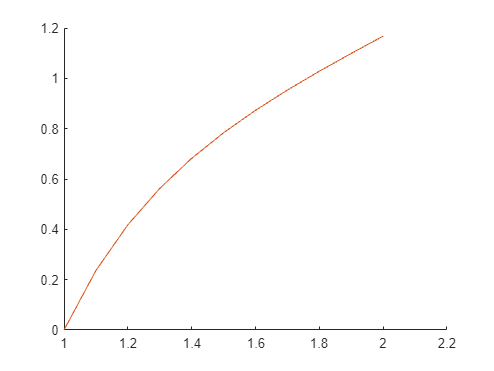

clc
clear
clf ('reset')
x0 = 1;
xn = 2;
y0 = 0;
h = 0.1;
[X1,Y1] = RungeKutta4(x0, xn, y0, h);
Y2=zeros(1,11);
Y3=zeros(1,11);
for i=1:11
Y2(i)=abs(Y1(i)-X1(i).^(-2)*(exp(X1(i))-exp(1)));
Y3(i)=X1(i).^(-2)*(exp(X1(i))-exp(1));
end
Y2=Y2.';
Y3=Y3.';
hold on
plot(X1,Y1);
plot(X1,Y3);
hold off

TAB=table(X1,Y1,Y3,Y2)

TAB = 11×4 table
    X1       Y1         Y3           Y2    
    ___    _______    _______    __________

      1          0          0             0
    1.1    0.23627    0.23627    2.5183e-06
    1.2    0.41794    0.41794    3.3896e-06
    1.3    0.56273    0.56273    3.5622e-06
    1.4     0.6821     0.6821    3.4403e-06
    1.5    0.78373    0.78374    3.2029e-06
    1.6    0.87295    0.87295    2.9308e-06
    1.7    0.95351    0.95352    2.6603e-06
    1.8     1.0282     1.0282    2.4066e-06
    1.9     1.0991     1.0991    2.1753e-06
      2     1.1677     1.1677    1.9674e-06
